mode = 2; sampnum = 4;

sampnum = 4

  Columns 1 through 3,276

    0.0523    0.2529   -0.0346    0.0666    0.0976   -0.0718    0.2090    0.2773    0.3479    0.4259    0.6869    0.7790    0.6176    0.6343    0.5694    0.9966    0.7588    0.8576    1.0022    1.0823    1.0692    0.9579    0.8409    0.8661    0.5650    0.4162    0.5474    0.3436    0.5173    0.4132    0.4373    0.7027    1.0420    0.9987    0.7271    0.4967    0.3195    0.0547   -0.2230   -0.0966   -0.5762   -0.6967   -0.6881   -0.7601   -0.8214   -0.7922   -0.5813   -0.3239   -0.0459    0.0010    0.1679    0.0394    0.3248    0.3170    0.3658   -0.1371   -0.6442   -0.9969   -1.2252   -1.7043   -1.9556   -1.9680   -2.2578   -1.9920   -1.9961   -1.7942   -1.4855   -1.0741   -0.8957   -0.5734   -0.4364   -0.2879   -0.2155   -0.5239   -0.7190   -0.7370   -0.8067   -1.3266   -1.3515   -1.3606   -1.5260   -1.3276   -1.3706   -1.6070   -1.6832   -1.6159   -1.8908   -1.9112   -1.7894   -1.2778   -1.2814   -0.8228   -0.3799   -0.2168   -0.3186   -0.4110   -0.3624   

  Columns 1 through 3,276

         0         0         0         0         0    0.0089    0.0208    0.0282    0.0434    0.0506    0.0298         0         0         0         0         0         0         0         0         0         0    0.0001    0.0239    0.0389    0.0595    0.0782    0.0875    0.1171    0.1135    0.1112    0.1062    0.0904    0.0682    0.0827    0.1161    0.1582    0.1790    0.1855    0.2149    0.1954    0.1995    0.2080    0.1980    0.1857    0.1911    0.1974    0.1906    0.1661    0.1639    0.1424    0.1067    0.1233    0.1093    0.1185    0.1100    0.1164    0.1353    0.1546    0.1792    0.2125    0.2112    0.2210    0.2563    0.2534    0.2696    0.2561    0.2363    0.2378    0.2376    0.2282    0.2305    0.2090    0.1803    0.1737    0.1579    0.1455    0.1286    0.1410    0.1517    0.1397    0.1295    0.1242    0.1254    0.1368    0.1458    0.1545    0.1795    0.1871    0.1937    0.1785    0.1711    0.1623    0.1634    0.1584    0.1451    0.1181    0.1030   

Size of reconstructed waveform:


          15       16000



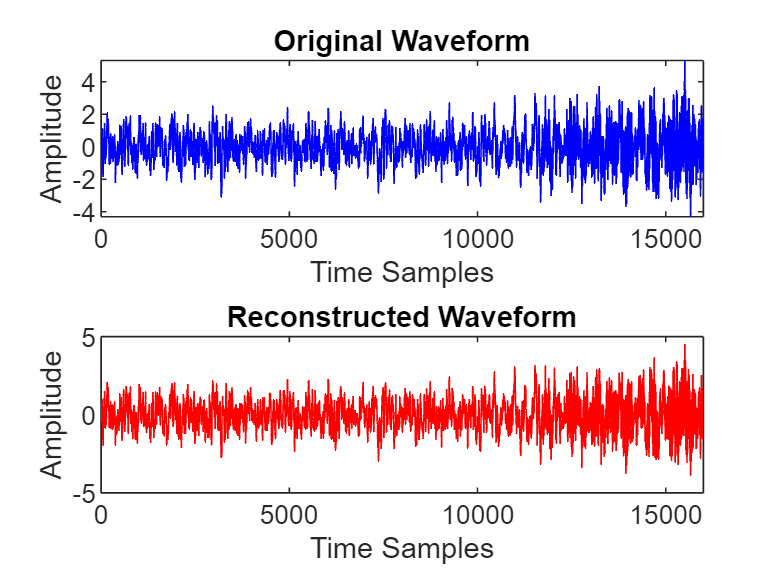

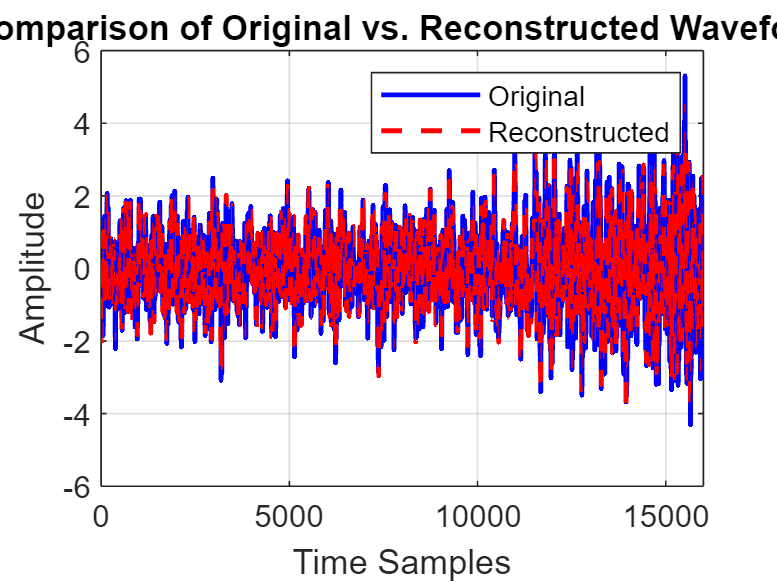

Mean Squared Error (MSE) for Audio File # 19: 0.012972


switch mode

    case 1
        reconstructedWaveform = predict(autoenc2, waveformData);
        
        encodedfeat = encode(autoenc2,waveformData);
        decoded = decode(autoenc2,encodedfeat);
        
        disp(decoded);
        disp(encodedfeat);
        disp("Size of reconstructed waveform:");
        disp(size(reconstructedWaveform));
        
        sampleIdx = sampnum; % Choose a test sample (1-15)
        original = waveformData(sampleIdx, :);  
        reconstructed = reconstructedWaveform(sampleIdx, :);
        
        figure;
        subplot(2,1,1);
        plot(original, 'b');
        title("Original Waveform");
        xlabel("Time Samples");
        ylabel("Amplitude");
        
        subplot(2,1,2);
        plot(reconstructed, 'r');
        title("Reconstructed Waveform");
        xlabel("Time Samples");
        ylabel("Amplitude");
        
        figure;
        plot(original, 'b', 'LineWidth', 1.5); hold on;
        plot(reconstructed, 'r--', 'LineWidth', 1.5);
        legend("Original", "Reconstructed");
        title("Comparison of Original vs. Reconstructed Waveform");
        xlabel("Time Samples");
        ylabel("Amplitude");
        grid on;
        
        mseError = mean((original - reconstructed).^2);
        fprintf("Mean Squared Error (MSE) for Audio File # %d: %.6f\n", sampleIdx, mseError);
    case 2
        testoffset = 15;
        reconstructedWaveform = predict(autoenc2, testwaveformData);
        encodedfeat = encode(autoenc2,testwaveformData);decoded = decode(autoenc2,encodedfeat);
        
        disp(decoded);
        disp(encodedfeat);
        disp("Size of reconstructed waveform:");
        disp(size(reconstructedWaveform));

        sampleIdx = sampnum; % Choose a test sample (1-15)
        original = testwaveformData(sampleIdx, :);  
        reconstructed = reconstructedWaveform(sampleIdx, :);
        
        figure;
        subplot(2,1,1);
        plot(original, 'b');
        title("Original Waveform");
        xlabel("Time Samples");
        ylabel("Amplitude");
        
        subplot(2,1,2);
        plot(reconstructed, 'r');
        title("Reconstructed Waveform");
        xlabel("Time Samples");
        ylabel("Amplitude");
        
        figure;
        plot(original, 'b', 'LineWidth', 1.5); hold on;
        plot(reconstructed, 'r--', 'LineWidth', 1.5);
        legend("Original", "Reconstructed");
        title("Comparison of Original vs. Reconstructed Waveform");
        xlabel("Time Samples");
        ylabel("Amplitude");
        grid on;
        
        mseError = mean((original - reconstructed).^2);
        fprintf("Mean Squared Error (MSE) for Audio File # %d: %.6f\n", sampleIdx+testoffset, mseError);
end